clear; clc; close all;

Ncells     = 48;          % # of cells (series)
SoA_max    = 1.0;         
dtSec      = 360;         % simulation tick
simHoursMax = 10000;      % max sim time
randomSeed = 100;         % rng seed

%% Intrinsic cell Parameters
slopeMin   = 1.0e-5;      % Base aging rate for the strongest cell [SoA/s]
slopeMax   = 1.4e-5;      % Base aging rate for the weakest cell

%% Realistic aging model parameters
initial_SoA_max = 0.1;    % Max initial SoA defect (0 to 0.1)
m_exponent = 1.2;         % Non-linear stress from high peak currents for real world condition sim
A_accel    = 0.5;         % Cell degradation for becoming too hot for real world condition sim

%% Controller gains
P_gain     = 0.5;         % Proportional gain
I_gain     = 0.02;        % Integral gain
D_gain     = 1.5;         % Derivative gain
Fuzzy_gain = 0.2;         % Fuzzy Logic gain

%% Initialization
nStepsMax = round(simHoursMax * 3600 / dtSec);
Tvector   = (0:nStepsMax).' * dtSec;

if ~isempty(randomSeed), rng(randomSeed); end
k_true = slopeMin + (slopeMax - slopeMin) * rand(Ncells,1);
SoA_initial = initial_SoA_max * rand(Ncells, 1);

strategy_names = {'Uncontrolled', 'PI Balancer', 'PD Balancer', 'Fuzzy Logic', 'Water-fill'};
num_strategies = length(strategy_names);

%% For keeping data
T_failure_hr = cell(num_strategies, 1);
computation_time_sec = cell(num_strategies, 1);
SoA_hist     = cell(num_strategies, 1);

%% ========== RUN ALL SIMULATIONS ============================
for method = 1:num_strategies
    strategy = strategy_names{method};
    fprintf('Running Simulation for: %-25s...', strategy);
    SoA_current = SoA_initial;
    SoA_log = zeros(Ncells, nStepsMax + 1);
    SoA_log(:,1) = SoA_current;
    total_comp_time = 0;
    
    u = ones(Ncells, 1) / Ncells; % Default usage
    if strcmp(strategy, 'PI Balancer'), I_term = zeros(Ncells, 1);
    elseif strcmp(strategy, 'Water-fill')
        k_nominal = ones(Ncells, 1) * mean([slopeMin, slopeMax]);
    end
    
    for s = 1:nStepsMax
        SoA_previous = SoA_log(:,s);
        aging_rate_previous = (SoA_current - SoA_previous) / dtSec;
        
        tic;
        if strcmp(strategy, 'PI Balancer')
            [u, I_term] = pi_controller(SoA_current, Ncells, P_gain, I_gain, I_term, dtSec);
        elseif strcmp(strategy, 'PD Balancer')
            u = pd_controller(SoA_current, Ncells, P_gain, D_gain, aging_rate_previous);
        elseif strcmp(strategy, 'Fuzzy Logic')
            u = fuzzy_controller(SoA_current, Ncells, aging_rate_previous, Fuzzy_gain);
        elseif strcmp(strategy, 'Water-fill')
            u = linear_waterfill_controller(SoA_current, k_nominal, dtSec);
        end
        total_comp_time = total_comp_time + toc;
        
        aging_rate_true = k_true .* (u .^ m_exponent) .* (1 + A_accel * SoA_current.^2);
        SoA_current = SoA_current + aging_rate_true * dtSec;
        SoA_log(:, s+1) = SoA_current;
        
        if max(SoA_current) >= SoA_max
            T_failure_hr{method} = Tvector(s+1) / 3600;
            computation_time_sec{method} = total_comp_time;
            SoA_hist{method} = SoA_log(:, 1:s+1);
            fprintf(' Failed at %.0f hours. Controller CPU time: %.4f s\n', T_failure_hr{method}, total_comp_time);
            break;
        end
    end
end

Running Simulation for: Uncontrolled             ...

 Failed at 1645 hours. Controller CPU time: 0.0020 s


Running Simulation for: PI Balancer              ...

 Failed at 1751 hours. Controller CPU time: 0.0173 s


Running Simulation for: PD Balancer              ...

 Failed at 2015 hours. Controller CPU time: 0.0255 s


Running Simulation for: Fuzzy Logic              ...

 Failed at 2025 hours. Controller CPU time: 0.1063 s


Running Simulation for: Water-fill               ...

 Failed at 2023 hours. Controller CPU time: 0.0531 s



%%For result plotting
fprintf('\n--- FINAL LIFETIME & COST RESULTS ---\n');


--- FINAL LIFETIME & COST RESULTS ---


computation_time_sec{1} = 0;
results_table = table(strategy_names', cell2mat(T_failure_hr), cell2mat(computation_time_sec), ...
    'VariableNames', {'Strategy', 'Lifetime_hours', 'ComputationTime_sec'});
disp(results_table);

        Strategy        Lifetime_hours    ComputationTime_sec
    ________________    ______________    ___________________

    {'Uncontrolled'}          1645                    0      
    {'PI Balancer' }        1751.4             0.017284      
    {'PD Balancer' }        2014.8             0.025521      
    {'Fuzzy Logic' }          2025              0.10626      
    {'Water-fill'  }          2023             0.053092      



[best_perf, best_idx] = max(results_table.Lifetime_hours);
fprintf('\nBest performing practical strategy: %s (%.0f hours)\n', results_table.Strategy{best_idx}, best_perf);


Best performing practical strategy: Fuzzy Logic (2025 hours)


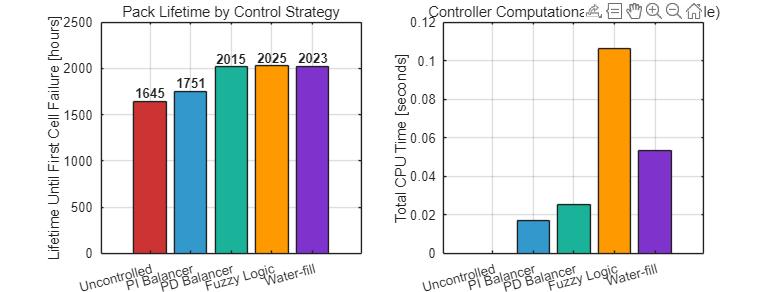

colors = {[0.8 0.2 0.2], [0.2 0.6 0.8], [0.1 0.7 0.6], [1.0 0.6 0.0], [0.5 0.2 0.8]};
figure('Name', 'Performance vs. Cost', 'Position', [50 500 1200 450]);
subplot(1, 2, 1);
bar_data = results_table.Lifetime_hours;
b = bar(bar_data); b.FaceColor = 'flat';
for i = 1:num_strategies, b.CData(i,:) = colors{i}; end
grid on; title('Pack Lifetime by Control Strategy');
ylabel('Lifetime Until First Cell Failure [hours]');
set(gca, 'xticklabel', results_table.Strategy); xtickangle(15);
text(1:num_strategies, bar_data, sprintfc('%.0f', bar_data), ...
    'vert', 'bottom', 'horiz', 'center', 'FontSize', 10, 'FontWeight', 'bold');
subplot(1, 2, 2);
bar_data_time = results_table.ComputationTime_sec;
b = bar(bar_data_time); b.FaceColor = 'flat';
for i = 1:num_strategies, b.CData(i,:) = colors{i}; end
grid on; title('Controller Computational Cost (Linear Scale)');
ylabel('Total CPU Time [seconds]');
set(gca, 'xticklabel', results_table.Strategy); xtickangle(15);

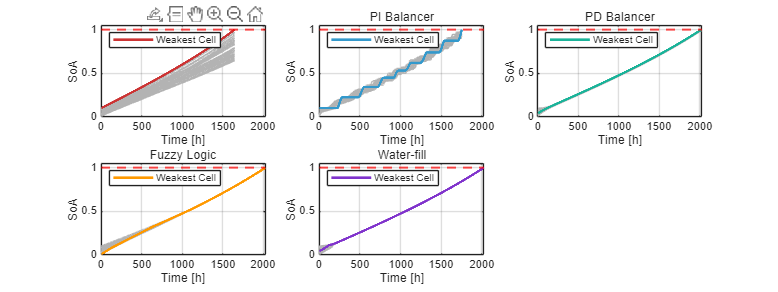


figure('Name', 'SoA Evolution of All 48 Cells', 'Position', [50 50 1600 600]);
T_max_plot = max(cell2mat(T_failure_hr));
for method = 1:num_strategies
    subplot(2, 3, method); % 2x3 grid is still good for 5 plots + empty space
    T_plot_vec = Tvector(1:size(SoA_hist{method}, 2));
    plot(T_plot_vec/3600, SoA_hist{method}, 'Color', [0.7 0.7 0.7]); hold on;
    [~, weakest_idx] = max(SoA_hist{method}(:, end));
    p_weakest = plot(T_plot_vec/3600, SoA_hist{method}(weakest_idx,:), 'Color', colors{method}, 'LineWidth', 2);
    yline(SoA_max, 'r--', 'LineWidth', 1.5); hold off;
    grid on; title(sprintf('%s', strategy_names{method}));
    xlabel('Time [h]'); ylabel('SoA');
    xlim([0 T_max_plot]); ylim([0 SoA_max*1.05]);
    legend(p_weakest, 'Weakest Cell', 'Location', 'northwest', 'AutoUpdate', 'off');
end

%% Controllers

function [u, I_term_new] = pi_controller(SoA, N, P_gain, I_gain, I_term_old, dt) % PI 컨트롤러
    
    soa_avg = mean(SoA); % 지금 팩의 평균 SoA가 어느 정도인지 계산하고
    error = SoA - soa_avg; % 각 셀이 평균에서 얼마나 벗어났는지(p_error)를 구함
    I_term_new = I_term_old + error * dt; % I 계산

    u = (1/N) - P_gain * error - I_gain * I_term_new; %현재 에러 (P)와 누적된 에러(I) 비례해서 control함
    u = max(0, u);
    u = u / sum(u);
end

function u = pd_controller(SoA, N, P_gain, D_gain, aging_rate) % PD 컨트롤러
    soa_avg = mean(SoA); %PI 랑 비슷함
    p_error = SoA - soa_avg; 
    aging_rate_avg = mean(aging_rate); 
    d_error = aging_rate - aging_rate_avg;
    u = (1/N) - P_gain * p_error - D_gain * d_error; %현재 에러와 derivative에 비례해서 control함
    u = max(0, u);
    u = u / sum(u);
end

function u = fuzzy_controller(SoA, N, aging_rate, F_gain) % 퍼지 로직
    soa_avg = mean(SoA); 
    aging_rate_avg = mean(aging_rate); 
    soa_error = SoA - soa_avg; 
    aging_rate_error = aging_rate - aging_rate_avg;

    soa_thresh = std(soa_error); %Fuzzification 표준편차를 써서 cell 들이 분포한 정도에 맞춰서 기준이 동적으로 control됨
    rate_thresh = std(aging_rate_error); 
    if rate_thresh < 1e-9, rate_thresh = 1e-9; end % 0으로 나누는 것 방지
    
    % Fuzzy rules
    adj = zeros(N,1); 
    adj(soa_error > soa_thresh) = adj(soa_error > soa_thresh) + 1; % 규칙 1: SoA가 높으면 사용량을 줄여야 함 (+1점)
    adj(soa_error < -soa_thresh) = adj(soa_error < -soa_thresh) - 1; % 규칙 2: SoA가 낮으면 사용량을 늘려야 함 (-1점)
    adj(aging_rate_error > rate_thresh) = adj(aging_rate_error > rate_thresh) + 1; % 규칙 3: 노화 속도가 빠르면 사용량을 줄여야 함 (+1점) 
    adj(aging_rate_error < -rate_thresh) = adj(aging_rate_error < -rate_thresh) - 1; % 규칙 4: 노화 속도가 느리면 사용량을 늘려야 함 (-1점)
    
    u = (1/N) - F_gain * adj / N; %Defuzzification
    u = max(0, u);
    u = u / sum(u);
end

function u = linear_waterfill_controller(SoA, k_nominal, dt) % Water-fill 컨트롤러 (linear model 가정함)

    
    lo = max(SoA); % lo, hi는 목표 water level, s값을 찾기 위한 탐색 범위
    hi = lo + mean(k_nominal) * dt;
    
    function g = total_load(target_s) %target_s 레벨로 모든 셀을 맞추기 (linear model 가정으로 총 사용량 계산함)
        u_trial = (target_s - SoA) ./ (k_nominal * dt); 
        u_clamped = max(0, min(1, u_trial)); %클램핑 값 제한용
        g = sum(u_clamped);
    end
    
    while total_load(hi) < 1, hi = hi + (hi - lo); end %탐색 범위 상한값 계산
    
    for i = 1:1 % s값 최적화 (실제 SoA 함수가 선형함수에서 멀수록 높이면됨)
        mid = (lo + hi) / 2; 
        if total_load(mid) > 1, hi = mid; % 목표값이 너무 높으면, 탐색 범위를 낮춤
        else, lo = mid; end % 목표값이 너무 낮으면, 탐색 범위를 높임
    end
    s = (lo + hi) / 2; % 최적 s
    
    u = (s - SoA) ./ (k_nominal * dt); %찾은 최적s로 최종 사용량 계산
    u = max(0, min(1, u));
    u = u / sum(u);
end